Deflection in **z **and **y **at the **tip **versus time.

figure(1)
plot(time, u_blade_y(18,1:end-1), time, u_blade_z(18,1:end-1))
grid on; grid minor;
legend({'$u_y$ blade 1','$u_z$ blade 1'},"Interpreter","latex","Location","northwest")
xlabel('time [s]',"Interpreter","latex")
ylabel('deflections',"Interpreter","latex")

Deflection in **z (flapwise)**

figure(2)
plot(time, u_blade_z(18,1:end-1));
ylabel('$u_Z$ for tip',"Interpreter","latex")
xlabel('time [s]',"Interpreter","latex")
title('Flapwise deflection')
grid on; grid minor;

Deflection in **y (edgewise)**

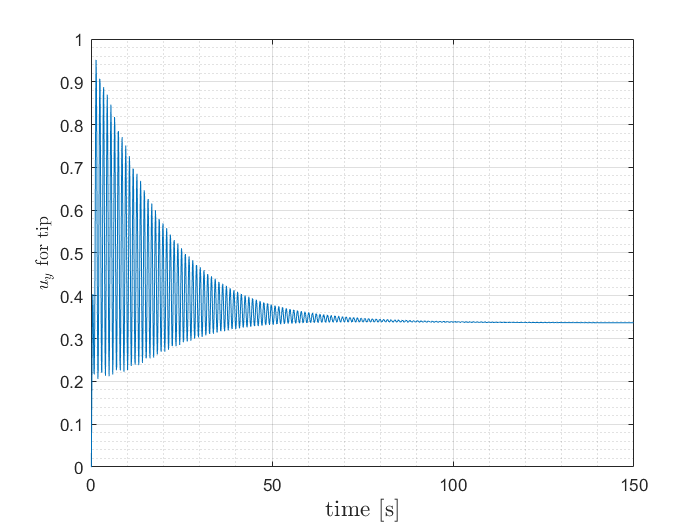

figure(3)
plot(time, u_blade_y(18,1:end-1));
ylabel('$u_y$ for tip',"Interpreter","latex")
xlabel('time [s]',"Interpreter","latex", 'FontSize',14)
% title('Edgewise deflection')
grid on; grid minor;

Tower position versus time. 

if DOF == 5
    figure(4)
    plot(time, u_tow_spring(1:end-1))
    ylabel('$u_{tower}$',"Interpreter","latex")
    xlabel('time [s]',"Interpreter","latex")
    grid on; grid minor;
end


[omega1f,omega1e,omega2f] = deal(3.93,6.10,11.28)

omega1f = 3.9300

omega1e = 6.1000

omega2f = 11.2800

% 
t_start_PSD = 0; % removes the first 70 seconds (transient)
t_end_PSD = Inf;
k_start_PSD = find(time>=t_start_PSD, 1, 'first');
k_end_PSD = find(time<=t_end_PSD, 1, 'last');
timesim_PSD = time(k_start_PSD:k_end_PSD); % transient removed
sampling_frequency = 1/dt;
nyquist_frequency = sampling_frequency/2;
n_parts_PSD = 4; %cuts the timeseries in 4 parts, this can be changed
window = hann(round(length(timesim_PSD)/n_parts_PSD), 'periodic');
noverlap = round(length(window)/2);
nperseg = length(window);
nfft = nperseg;

Uz deflection

disp('Uz PSD')

Uz PSD


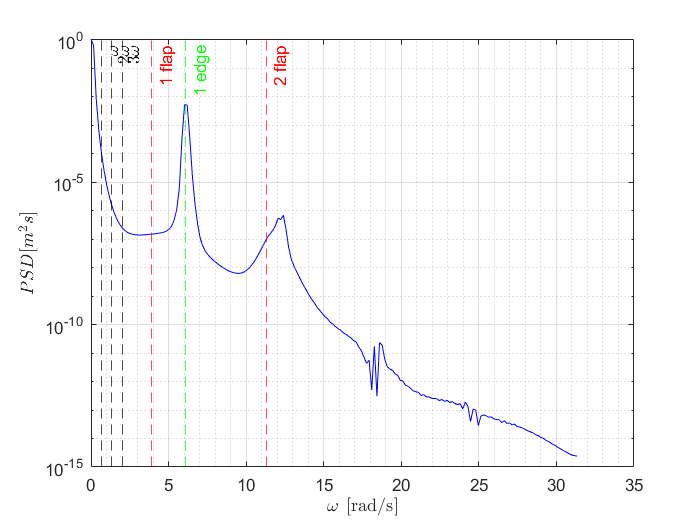

% % Apply Welch's method
figure(5)
uztip = u_blade_z(18,:); 
uztipmean = mean( uztip(k_start_PSD:k_end_PSD) );
[pow_PSD_uztip, frequency_uztip] = pwelch( uztip(k_start_PSD:k_end_PSD) - uztipmean, window, ...
 noverlap, nfft, sampling_frequency, 'psd');
% % loglog(frequency_uztip*2*pi, pow_PSD_uztip)
% % ylabel('$PSD [m^2s]$',"Interpreter","latex")
% % xlabel('frecuency [1/s]',"Interpreter","latex")
% % frequency_uztip;
% % grid on; grid minor;
semilogy(frequency_uztip*2*pi, pow_PSD_uztip, 'b')
ylabel('$PSD  [m^2s] $',"Interpreter","latex")
xlabel('$\omega$ [rad/s]',"Interpreter","latex")
grid on; grid minor;
xline(omega_1, '--k',{'$\omega$'},"Interpreter","latex")
xline(omega_1*2, '--k',{'2$\omega$'},"Interpreter","latex")
xline(omega_1*3, '--k',{'3$\omega$'},"Interpreter","latex")

xline(omega1f, '--r', {'1 flap'})
xline(omega1e, '--g', {'1 edge'})
xline(omega2f, '--r',{'2 flap'}); 

Uy_deflection

% Apply Welch's method

disp('Uy PSD')

Uy PSD


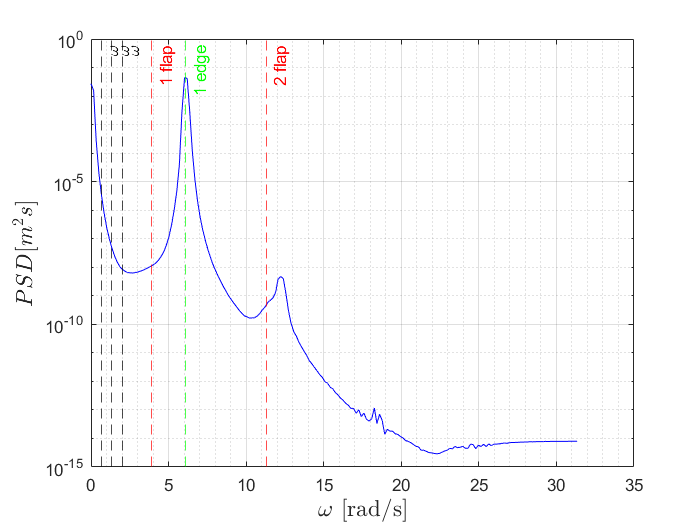

figure(6)
uytip = u_blade_y(18,:); 
uytipmean = mean( uytip(k_start_PSD:k_end_PSD) );
[pow_PSD_uytip, frequency_uytip] = pwelch( uytip(k_start_PSD:k_end_PSD) - uytipmean, window, ...
 noverlap, nfft, sampling_frequency, 'psd');
%loglog(frequency_uytip*2*pi, pow_PSD_uytip)
% ylabel('$PSD [m^2s]$',"Interpreter","latex")
% xlabel('$\omega$ [rad/s]',"Interpreter","latex")
% % grid on; grid minor;
semilogy(frequency_uytip*2*pi, pow_PSD_uytip, 'b')
ylabel('$PSD [m^2s]$',"Interpreter","latex",'FontSize',14)
xlabel('$\omega$ [rad/s]',"Interpreter","latex",'FontSize',14)
grid on;grid minor;
xline(omega_1, '--k',{'$\omega$'},"Interpreter","latex")
xline(omega_1*2, '--k',{'$\omega$'},"Interpreter","latex") 
xline(omega_1*3, '--k',{'$\omega$'},"Interpreter","latex")
xline(omega1f, '--r', {'1 flap'})
xline(omega1e, '--g', {'1 edge'})
xline(omega2f, '--r',{'2 flap'}); 

Flapwise bending moment

disp('Flapwise bending PSD')

Flapwise bending PSD


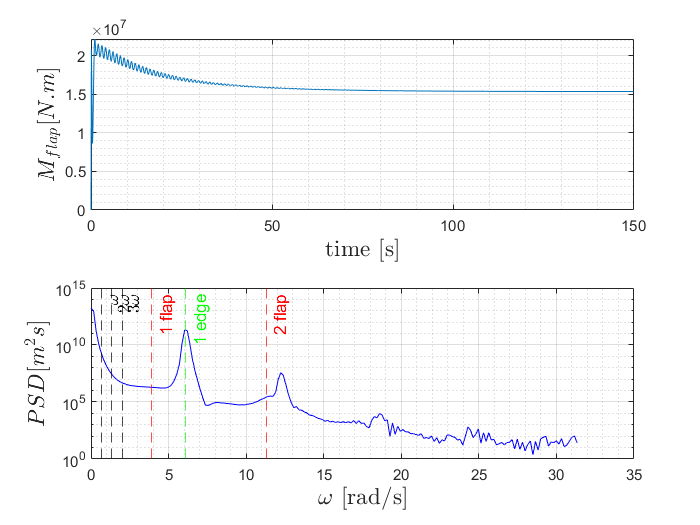

figure(7)
M_root_flap = trapz(r-r(1), (r-r(1)).*pn(:,1,:) );
M_root_flap1d = zeros(1,nt);
for nt = 1:nt_max
    M_root_flap1d(:,nt) = M_root_flap(1,:,nt);
end


subplot(2,1,1)
plot(time, M_root_flap1d);
ylabel('$M_{flap}[N.m]$',"Interpreter","latex",'FontSize',14)
xlabel('time [s]',"Interpreter","latex", 'FontSize',14)
% title('Edgewise deflection')
grid on; grid minor;

subplot(2,1,2)

mflapmean = mean( M_root_flap1d(k_start_PSD:k_end_PSD) );
[pow_PSD_mflap, frequency_mflap] = pwelch(M_root_flap1d (k_start_PSD:k_end_PSD) - mflapmean , window, ...
 noverlap, nfft, sampling_frequency, 'psd');

semilogy( frequency_mflap*2*pi, pow_PSD_mflap, 'b')
ylabel('$PSD [m^2s]$',"Interpreter","latex",'FontSize',14)
xlabel('$\omega$ [rad/s]',"Interpreter","latex",'FontSize',14)
grid on;grid minor;
xline(omega_1, '--k',{'$\omega$'},"Interpreter","latex")
xline(omega_1*2, '--k',{'2$\omega$'},"Interpreter","latex") 
xline(omega_1*3, '--k',{'3$\omega$'},"Interpreter","latex")
xline(omega1f, '--r', {'1 flap'})
xline(omega1e, '--g', {'1 edge'})
xline(omega2f, '--r',{'2 flap'})